# MaskRCNN Inference(五行 Code)

%Bulit on 2023.12.07 by Fred Liu

Need to Download Support Package：

**Computer Vision Toolbox Model for Mask R-CNN Instance Segmentation**

detector = solov2("resnet50-coco")

detector =   solov2 with properties:

     ModelName: "resnet50-coco"
    ClassNames: {1×80 cell}
     InputSize: [800 800 3]
     GridSizes: [12 16 24 36 40]


在resnet50-coco中有80種類別的物件可以辨識

因此這邊載入的是跟YOLOv4 Inference

img = imread('highway.jpg');    

可以調整Threshold的值域

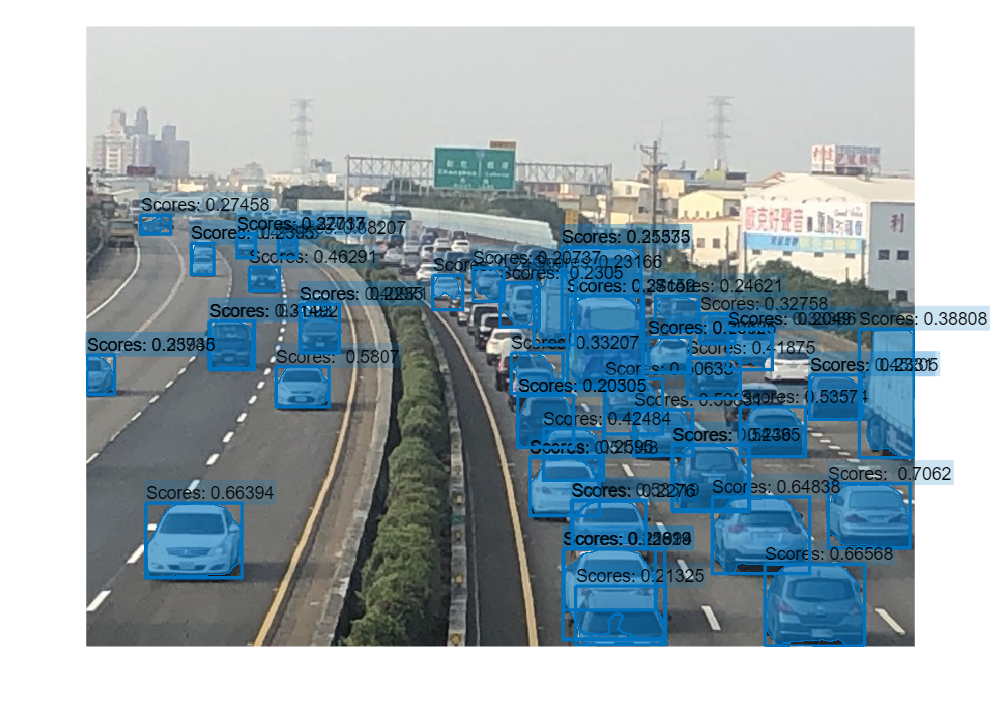

[masks,labels,scores] = segmentObjects(detector,img,Threshold=0.2);
overlayedImage = insertObjectMask(img,masks);
figure,imshow(overlayedImage)
boxes = getBoxFromMask(masks);
showShape("rectangle",boxes,Label="Scores: "+num2str(scores),LabelOpacity=0.2)

getBoxFromMask Function

function boxes = getBoxFromMask(masks)

for idx  = 1:size(masks,3)
    mask = masks(:,:,idx);
    [ptsR, ptsC] = find(mask);

    minR = min(ptsR);
    maxR = max(ptsR);
    minC = min(ptsC);
    maxC = max(ptsC);
    
    boxes(idx,:) = [minC minR maxC-minC maxR-minR];

end
end